assert(endsWith(pwd, "biological disk"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

#### Specimen properties

data = readmatrix('liver_properties.txt', 'CommentStyle','%');
f = data(:,1);
relative_permittivity = data(:,2);
conductivity          = data(:,3);

relative_permittivity_interpolant = griddedInterpolant(log(f),log(relative_permittivity));
conductivity_interpolant          = griddedInterpolant(log(f),log(conductivity));

relative_permittivity_func = @(f)exp(relative_permittivity_interpolant(log(f)));
conductivity_func          = @(f)exp(conductivity_interpolant(log(f)));

clear f relative_permittivity conductivity relative_permittivity_interpolant conductivity_interpolant

## Uniform Grid

#### Electromagnet

EM.num = 1;
EM.inner_radius = 3.75e-3; % (m)
EM.outer_radius = 6.00e-3; % (m)
EM.length = 4.00e-3; % length (m)
EM.Nturns = 60;

EM.z = 5.00e-3; % (m)

#### Sensor

Sensor.num = 10;
Sensor.side_length = 0.8e-3;

Sensor.position = [linspace(6e-3,30e-3,Sensor.num); 2.5e-3*ones(1,Sensor.num)];

#### Model

disk.radius = 30e-3; % (m)
disk.height = 6e-3; % (m)
disk.n_r = 20; % number of elements in r direction
disk.n_z = 20; % number of elements in z direction

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildModel2D('Cylinder', r,z);

build model took 0.02 seconds


clear disk r z

Model.conductivity          = @(f)conductivity_func(f)          * ones(1,Model.num_elms); % (S/m)
Model.relative_permittivity = @(f)relative_permittivity_func(f) * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, EM);

build governing equation took 83.53 seconds


#### Solve in frequency domain

EM.frequency_domain.current = 1; % (A)
EM.frequency_domain.current_density = EM.frequency_domain.current * EM.Nturns / ((EM.outer_radius-EM.inner_radius)*EM.length); % (A/m^2)
EM.frequency_domain.frequency = 20000; % (Hz)

[Model, EM, Sensor] = SolveFrequencyDomain2D(GoverningEquation, Model, EM, Sensor);

solve current density took 0.05 seconds
solve magnetic flux density took 8.51 seconds


#### Plot result

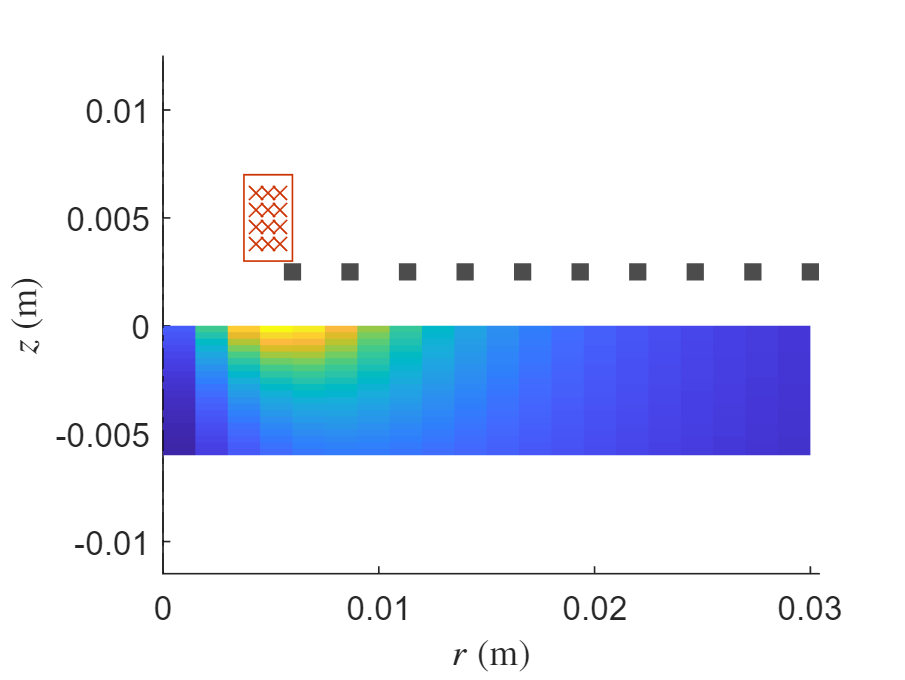

PlotWorld2D(Model, EM, Sensor, abs(Model.frequency_domain.J));

clf

## Compare with FEA

#### Current density

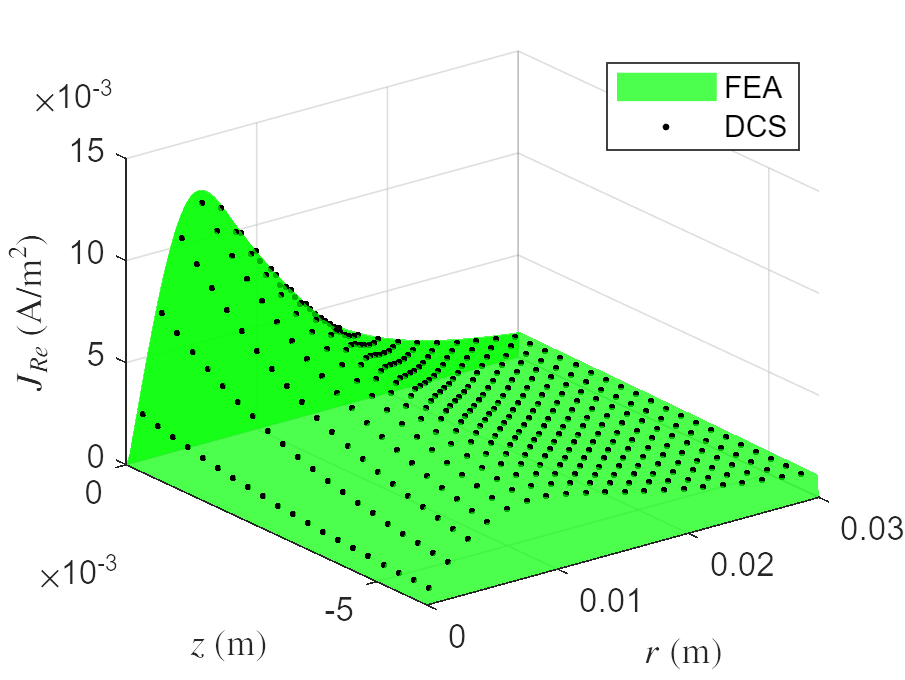

data = readmatrix('FEA_data/J.csv', 'CommentStyle','%');
FEA.r_model = reshape(data(:,1), 200, []);
FEA.z_model = reshape(data(:,2), 200, []);
FEA.J = reshape(data(:,3), 200, []);

surf(FEA.r_model,FEA.z_model, real(FEA.J), 'DisplayName','FEA', 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
hold on
plot3(Model.elms_center(1,:), Model.elms_center(2,:), real(Model.frequency_domain.J), 'k.', 'DisplayName','DCS')
legend('show', 'Location','best');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Re}$ (A/m$^2$)", 'Interpreter','latex')
hold off

clf

FEA.J_Re_interpolant = griddedInterpolant(FEA.r_model,FEA.z_model, real(FEA.J));
J_FEA = FEA.J_Re_interpolant(Model.elms_center(1,:), Model.elms_center(2,:));
J_DSC = real(Model.frequency_domain.J);
relative_error = mean(abs((J_DSC - J_FEA) ./ J_FEA));
fprintf("average relative error: %f", relative_error)

average relative error: 0.001467

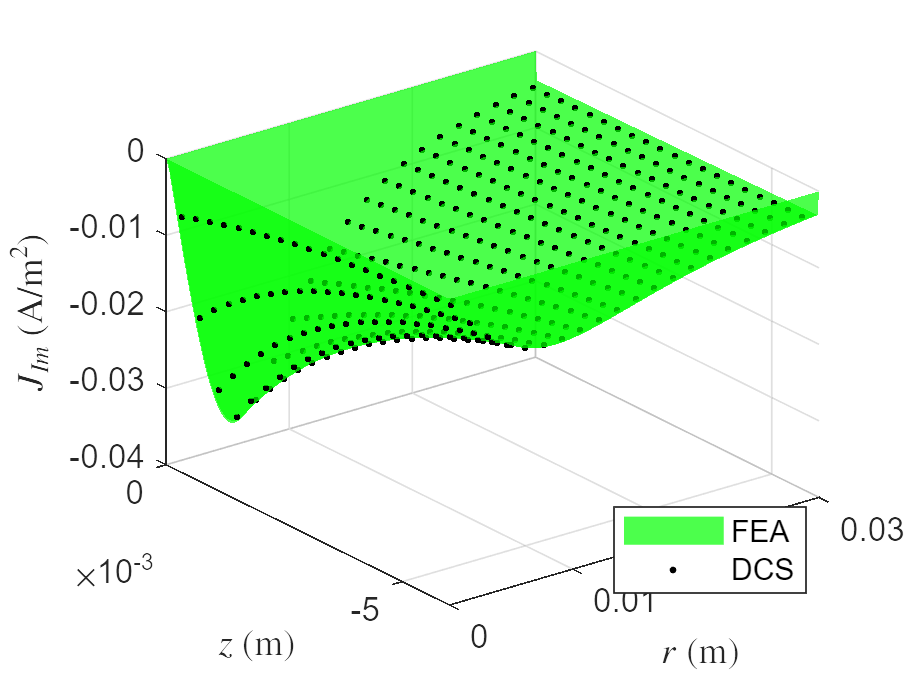


surf(FEA.r_model,FEA.z_model, imag(FEA.J), 'DisplayName','FEA', 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
hold on
plot3(Model.elms_center(1,:), Model.elms_center(2,:), imag(Model.frequency_domain.J), 'k.', 'DisplayName','DCS')
legend('show', 'Location','best');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Im}$ (A/m$^2$)", 'Interpreter','latex')
hold off

clf

FEA.J_Im_interpolant = griddedInterpolant(FEA.r_model,FEA.z_model, imag(FEA.J));
J_FEA = FEA.J_Im_interpolant(Model.elms_center(1,:), Model.elms_center(2,:));
J_DSC = imag(Model.frequency_domain.J);
relative_error = mean(abs((J_DSC - J_FEA) ./ J_FEA));
fprintf("average relative error: %f", relative_error)

average relative error: 0.000934


clear data J_FEA J_DSC relative_error

#### Magnetic flux density

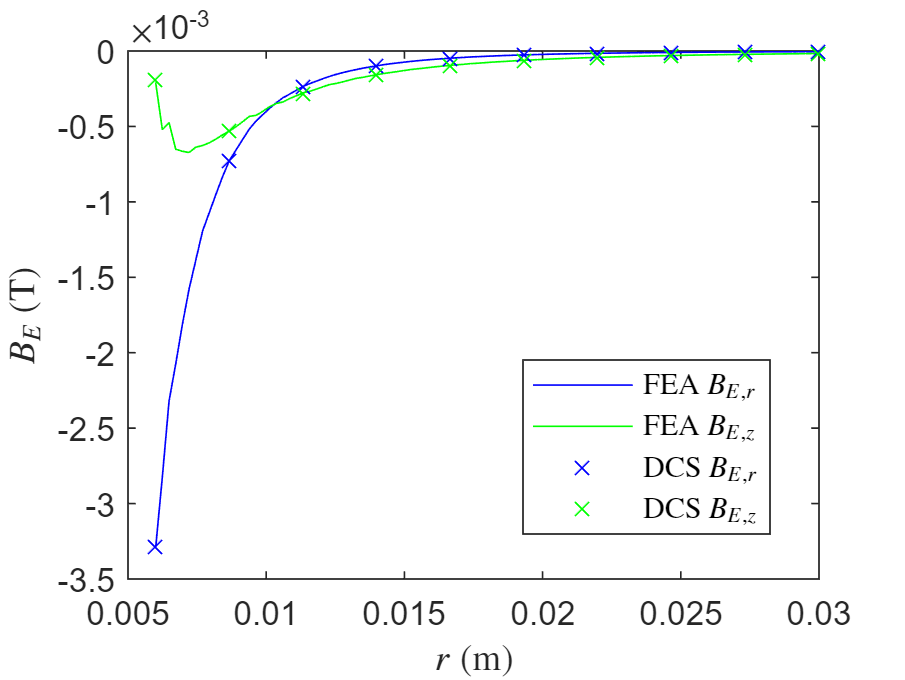

data = readmatrix('FEA_data/B_E.csv', 'CommentStyle','%');
FEA.r_sensor = data(:,1);
FEA.B_E_r = data(:,3);
FEA.B_E_z = data(:,4);
data = readmatrix('FEA_data/B_E_plus_B_C.csv', 'CommentStyle','%');
FEA.r_sensor = data(:,1);
FEA.B_C_r = data(:,3) - FEA.B_E_r;
FEA.B_C_z = data(:,4) - FEA.B_E_z;
clear data

plot(FEA.r_sensor, FEA.B_E_r, 'b-', 'DisplayName','FEA $B_{E,r}$'); hold on
plot(FEA.r_sensor, FEA.B_E_z, 'g-', 'DisplayName','FEA $B_{E,z}$');
plot(Sensor.position(1,:), Sensor.frequency_domain.B_E(1,:), 'bx', 'DisplayName','DCS $B_{E,r}$')
plot(Sensor.position(1,:), Sensor.frequency_domain.B_E(2,:), 'gx' ,'DisplayName','DCS $B_{E,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')
hold off

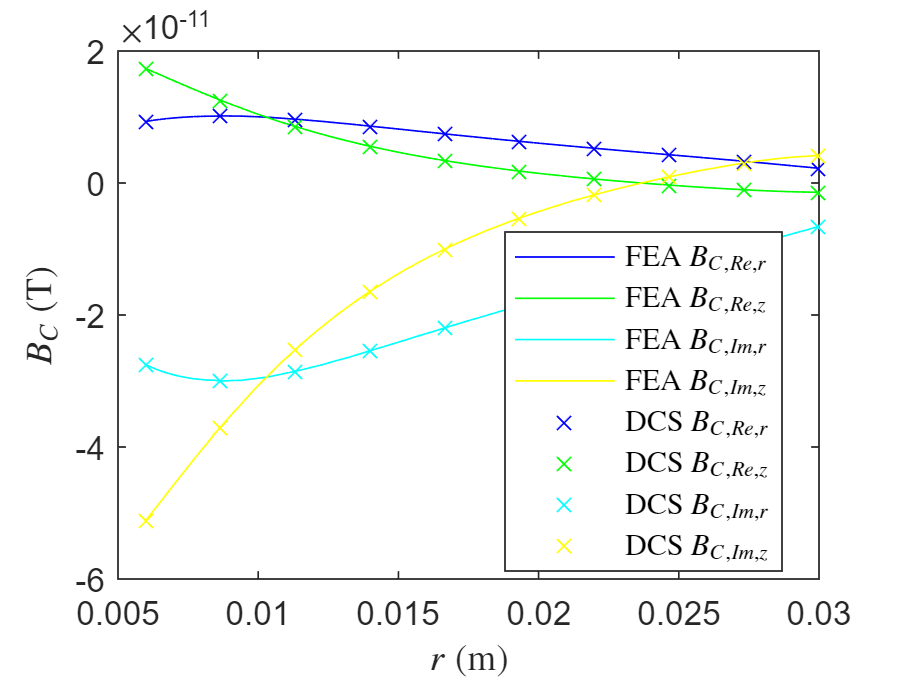

clf

plot(FEA.r_sensor, real(FEA.B_C_r), 'b-', 'DisplayName','FEA $B_{C,Re,r}$'); hold on
plot(FEA.r_sensor, real(FEA.B_C_z), 'g-', 'DisplayName','FEA $B_{C,Re,z}$');
plot(FEA.r_sensor, imag(FEA.B_C_r), 'c-', 'DisplayName','FEA $B_{C,Im,r}$');
plot(FEA.r_sensor, imag(FEA.B_C_z), 'y-', 'DisplayName','FEA $B_{C,Im,z}$');
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(1,:)), 'bx', 'DisplayName','DCS $B_{C,Re,r}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(2,:)), 'gx' ,'DisplayName','DCS $B_{C,Re,z}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(1,:)), 'cx', 'DisplayName','DCS $B_{C,Im,r}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(2,:)), 'yx' ,'DisplayName','DCS $B_{C,Im,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')
hold off

clf

## Frequency Sweep

#### Plot specimen properties

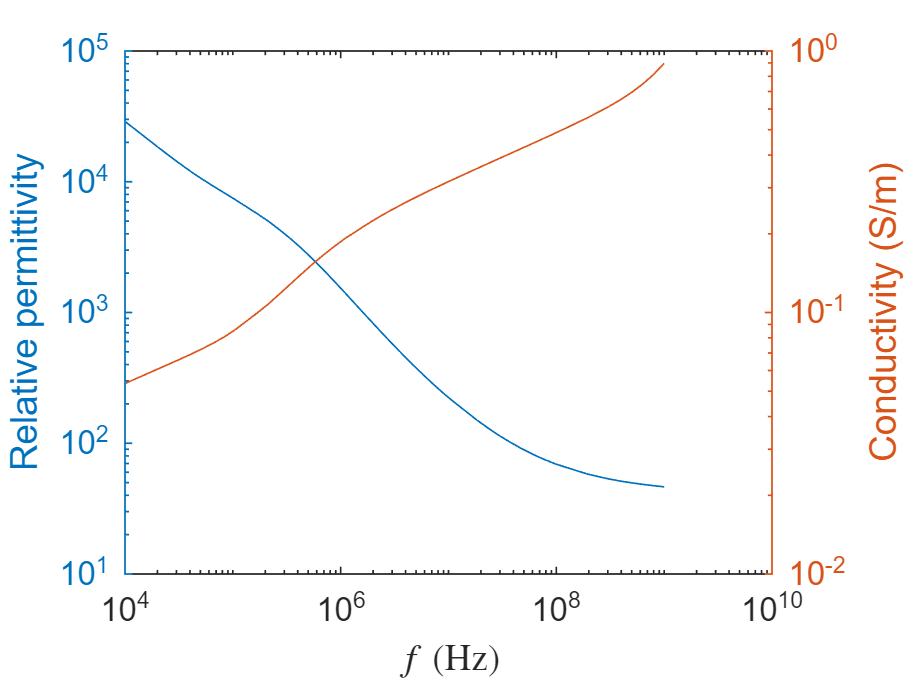

f_points = logspace(4, 9);

yyaxis left
loglog(f_points, relative_permittivity_func(f_points))
ylabel("Relative permittivity")
yyaxis right
loglog(f_points, conductivity_func(f_points))
ylabel("Conductivity (S/m)")
xlabel("$f$ (Hz)", 'Interpreter','latex')

clf

#### Magnetic flux density

Sensor2.num = 1;
Sensor2.position = [6e-3 2.5e-3]';

B_C = zeros(2, numel(f_points));
for i = 1:numel(f_points)
    f = f_points(i);
    EM.frequency_domain.frequency = f;
    [Model, EM, Sensor2] = SolveFrequencyDomain2D(GoverningEquation, Model, EM, Sensor2);
    B_C(:,i) = Sensor2.frequency_domain.B_C;
end

solve current density took 0.04 seconds
solve magnetic flux density took 0.81 seconds
solve current density took 0.03 seconds
solve magnetic flux density took 0.60 seconds
solve current density took 0.03 seconds
solve magnetic flux density took 0.52 seconds
solve current density took 0.03 seconds
solve magnetic flux density took 0.61 seconds
solve current density took 0.03 seconds
solve magnetic flux density took 0.65 seconds
solve current density took 0.03 seconds
solve magnetic flux density took 0.62 seconds
solve current density took 0.02 seconds
solve magnetic flux density took 0.48 seconds
solve current density took 0.02 seconds
solve magnetic flux density took 0.47 seconds
solve current density took 0.02 seconds
solve magnetic flux density took 0.47 seconds
solve current density took 0.03 seconds
solve magnetic flux density took 0.48 seconds
solve current density took 0.02 seconds
solve magnetic flux density took 0.47 seconds
solve current density took 0.02 seconds
solve magnetic

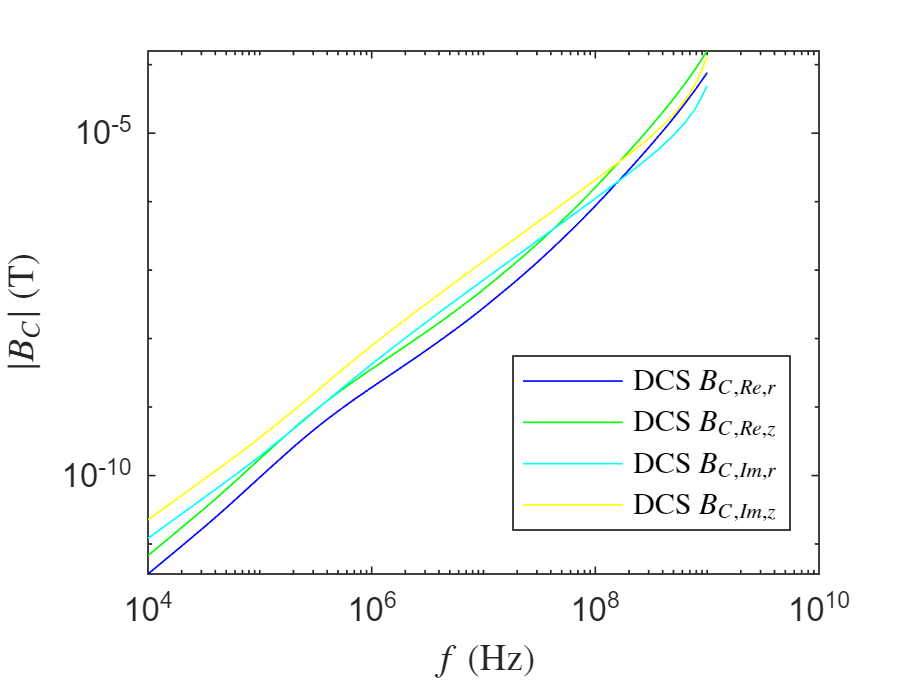


loglog(f_points, abs(real(B_C(1,:))), 'b-', 'DisplayName','DCS $B_{C,Re,r}$'); hold on
loglog(f_points, abs(real(B_C(2,:))), 'g-' ,'DisplayName','DCS $B_{C,Re,z}$')
loglog(f_points, abs(imag(B_C(1,:))), 'c-', 'DisplayName','DCS $B_{C,Im,r}$')
loglog(f_points, abs(imag(B_C(2,:))), 'y-' ,'DisplayName','DCS $B_{C,Im,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$f$ (Hz)", 'Interpreter','latex')
ylabel("$|B_C|$ (T)", 'Interpreter','latex')
hold off

clf

clear f_points f i B_C